clear; close all; clc;

**Question 3: Implement a matrix-free regularised least-squares solver for the Radon Transform.**

Setup:

n = 64;

sigma = 0.1;

f_true = phantom(n);
f_noisy = f_true + randn(n) * sigma;

        i) Keeping the range of angles from 0 to 180 but varying the number of projections. E.g angles = [0:4:179] gives 45 projections at 4 degree seperation.

angles = 0 : 4 : 179;

R = @(f) iradon(radon(f, angles), angles, 'linear', 'none', 1, n);

Rf_true = R(f_true);
Rf_noisy = R(f_noisy);

alpha = 10;

ATA_handle = @(f) ATA(f, R, alpha, n);
rhs = reshape(Rf_noisy, [], 1);

tol = 10^-8;
max_it = 500;

fa = pcg(ATA_handle, rhs, tol, max_it);

pcg converged at iteration 17 to a solution with relative residual 9.6e-09.


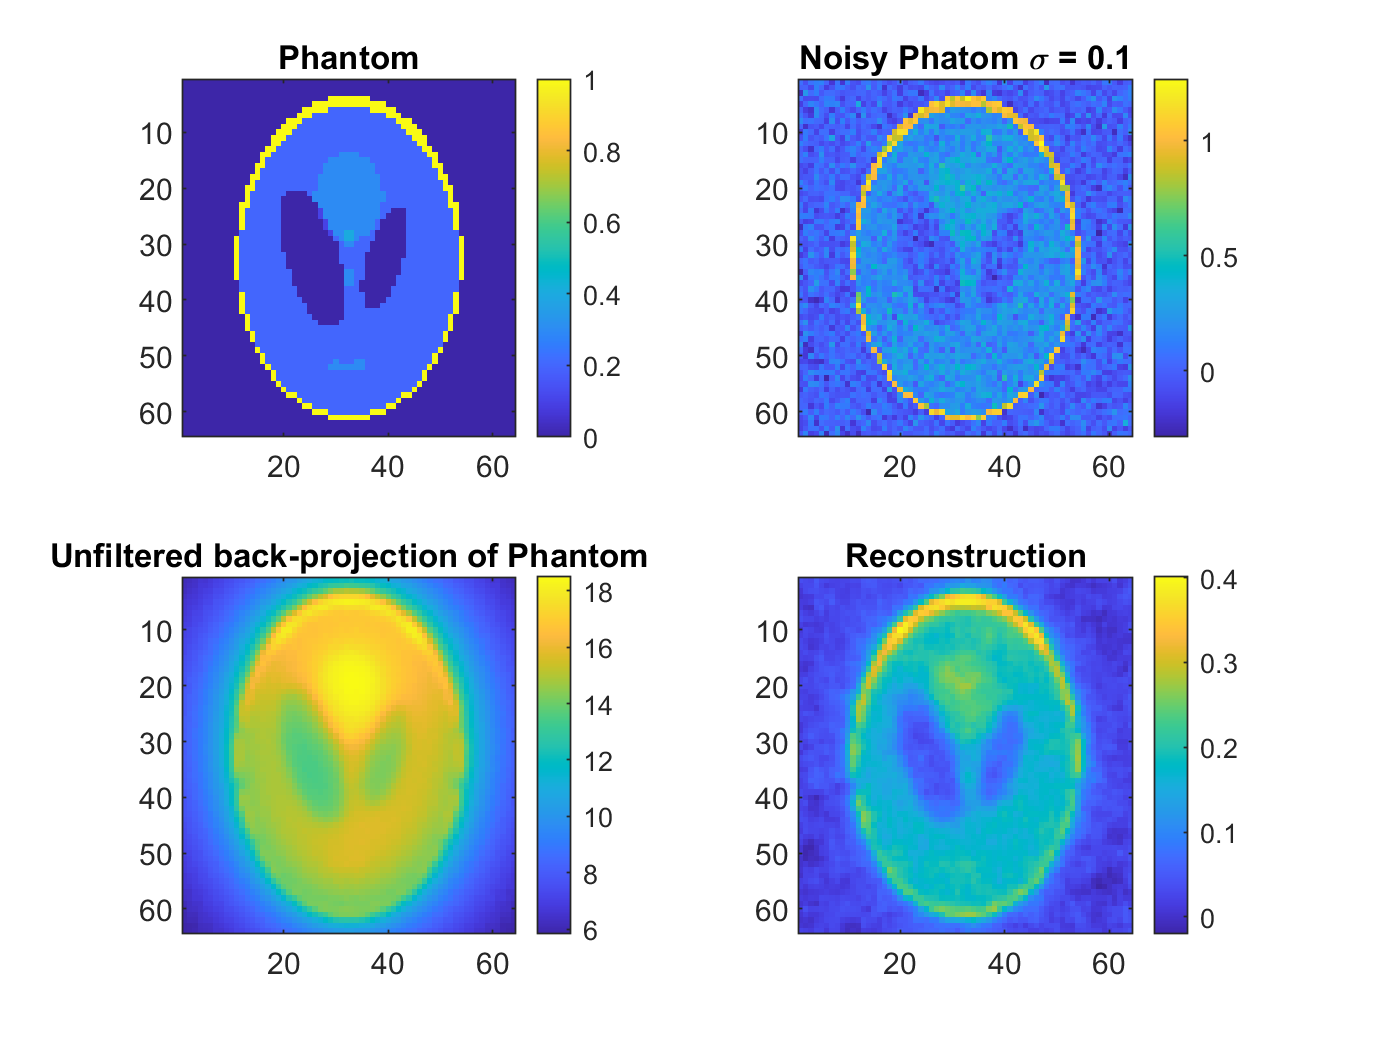

fa = reshape(fa, [64, 64]);

figure;
subplot(2, 2, 1); imagesc(f_true); colorbar; title('Phantom');
subplot(2, 2, 2); imagesc(f_noisy); colorbar; title(['Noisy Phatom \sigma = ' num2str(sigma)]);
subplot(2, 2, 3); imagesc(Rf_true); colorbar; title('Unfiltered back-projection of Phantom');
subplot(2, 2, 4); imagesc(fa); colorbar; title('Reconstruction');

clear; clc;

n = 64;

sigma = 0.1;

f_true = phantom(n);
f_noisy = f_true + randn(n) * sigma;

        ii) Keeping the number of projection the same, but varying the range to being less than 0 to 180 (i.e. limited angle). E.g. angles = [0:1:44] gives 45 projections over only a 45 degree range.

angles = 0 : 1 : 44;

R = @(f) iradon(radon(f, angles), angles, 'linear', 'none', 1, n);

Rf_true = R(f_true);
Rf_noisy = R(f_noisy);

alpha = 100;

ATA_handle = @(f) ATA(f, R, alpha, n);
rhs = reshape(Rf_noisy, [], 1);

tol = 10^-8;
max_it = 500;

fa = pcg(ATA_handle, rhs, tol, max_it);

pcg converged at iteration 9 to a solution with relative residual 9.1e-09.


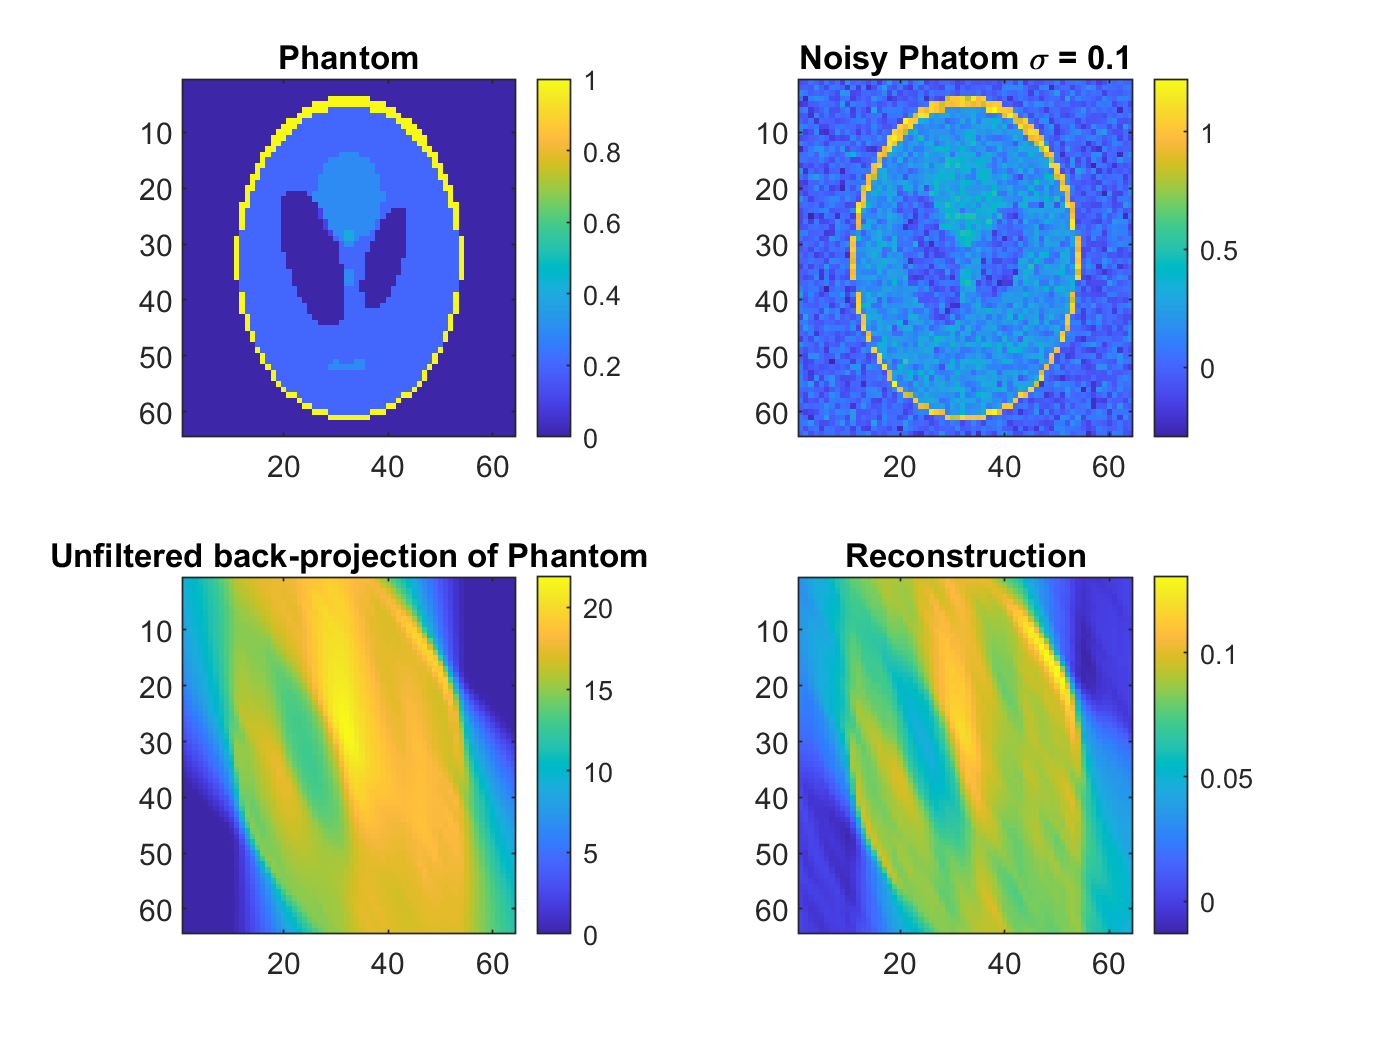

fa = reshape(fa, [64, 64]);

figure;
subplot(2, 2, 1); imagesc(f_true); colorbar; title('Phantom');
subplot(2, 2, 2); imagesc(f_noisy); colorbar; title(['Noisy Phatom \sigma = ' num2str(sigma)]);
subplot(2, 2, 3); imagesc(Rf_true); colorbar; title('Unfiltered back-projection of Phantom');
subplot(2, 2, 4); imagesc(fa); colorbar; title('Reconstruction');